clear;

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;

Nmax = randi([35,50])

Nmax = 47

errodf = 15e-2

errodf = 0.1500

x_values=[-11;-11]; y_values=[7;7];

PontosIniciais = [-6.0,-5.0,0.0;2.0,0.0,-2.0]

PontosIniciais =     -6    -5     0
     2     0    -2


lambda = 0.00005;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(r, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);

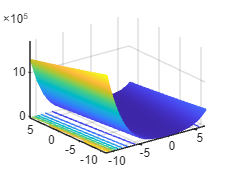

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

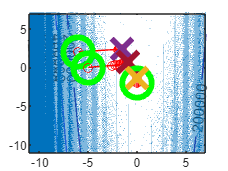


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

PontosIniciais = [2.0,-2.0,-2.0,2.0;5.0,5.0,-5.0,-5.0]

PontosIniciais =      2    -2    -2     2
     5     5    -5    -5


lambda = 0.0005;
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

[Lista, LNit, Lopt, dffinal] = steepest_descent_static(f, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);

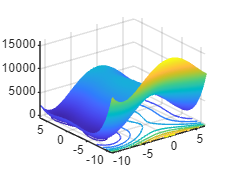

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

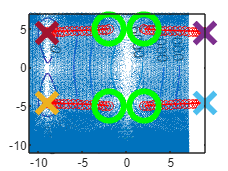


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

PontosIniciais = [2.0,2.0,0.0,0.0,-10.0;3.0,1.0,3.0,1.0,4.0]

PontosIniciais =      2     2     0     0   -10
     3     1     3     1     4


g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
lambda = 0.0005;
[Lista, LNit, Lopt, dffinal] = steepest_descent_static(g, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);

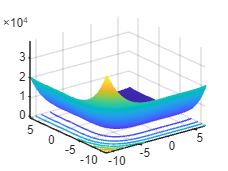

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

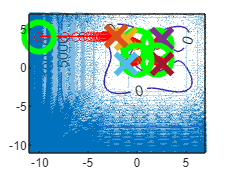


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off